# 1. 定点飞行HIL电机输出

clear
clc
 
ulogOBJ = ulogreader("log_0_2021-6-30-08-02-26.ulg");
msg = readTopicMsgs(ulogOBJ);

% 获取 unknown_logger 数据
logSampleRate = 50;
unknown_logger = msg.TopicMessages{32};
% 生成相对时间
log_time = unknown_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
tDes = unknown_logger.tdes;
chVDes = unknown_logger.chvdes;
psi = unknown_logger.psi;
% 处理数据
% 选取和HIL中模型一致的控制分配矩阵参数
c  = (0.0166);
l  = (0.125);
M = ([ 1          1          1         1;
      -0.7071*l  -0.7071*l   0.7071*l  0.7071*l;
       0.7071*l  -0.7071*l  -0.7071*l  0.7071*l;
       c         -c          c        -c]);
% 获取虚拟控制通道向量,即总的拉力和三个轴的力矩
vAct = zeros(sample_count,4);
for i = 1:sample_count
    vAct(i,:) = M*((tDes(i,:))');
end
% 获取实际的包含故障信息的虚拟控制通道向量
vActFault = zeros(sample_count,4);
for i = 1:sample_count
    vActFault(i,:) = M*((tDes(i,:))'.*[0,1,1,1]');
end

% 故障的时间段 30-60s
tfaultstart = 33;
tfaultend = 60;
samplevector = tfaultstart*logSampleRate:1:tfaultend*logSampleRate;

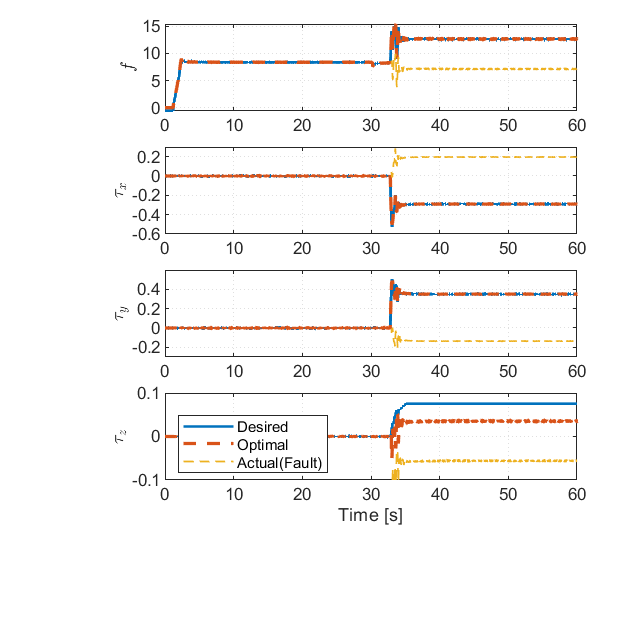

% 画图
figure(11);
clf
subplot(4,1,1)
plot(relativeTime, chVDes(:,1))
hold on 
plot(relativeTime, vAct(:,1),'--','LineWidth',2)
hold on
plot(relativeTime(samplevector),vActFault(samplevector,1),'--','LineWidth',1)
ylabel("$f$",'Interpreter',"latex")
xlim([0,60])

subplot(4,1,2)
plot(relativeTime, chVDes(:,2))
hold on 
plot(relativeTime, vAct(:,2),'--','LineWidth',2)
hold on
plot(relativeTime(samplevector),vActFault(samplevector,2),'--','LineWidth',1)
ylabel("$\tau_x$",'Interpreter',"latex")
xlim([0,60])
ylim([-0.6 0.3])

subplot(4,1,3)
plot(relativeTime, chVDes(:,3))
hold on 
plot(relativeTime, vAct(:,3),'--','LineWidth',2)
hold on
plot(relativeTime(samplevector),vActFault(samplevector,3),'--','LineWidth',1)
ylabel("$\tau_y$",'Interpreter',"latex")
xlim([0,60])
ylim([-0.3 0.6])

subplot(4,1,4)
plot(relativeTime, chVDes(:,4))
hold on 
plot(relativeTime, vAct(:,4),'--','LineWidth',2)
hold on
plot(relativeTime(samplevector),vActFault(samplevector,4),'--','LineWidth',1)
ylabel("$\tau_z$",'Interpreter',"latex")
xlim([0,60])
ylim([-0.1 0.1])

legend("Desired","Optimal", "Actual(Fault)",'Location',"southwest")
xlabel("Time [s]")

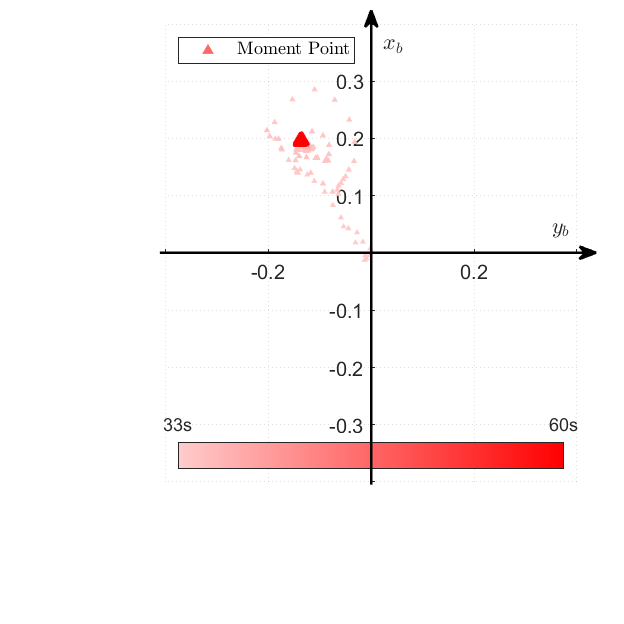

figure(12);
clf
[~,samplevectorLength] = size(samplevector);
% 第一条线的颜色大小
samplevectorcolorR = linspace(1, 1, samplevectorLength);
samplevectorcolorG = linspace(0.8, 0, samplevectorLength);
samplevectorcolorB = linspace(0.8, 0, samplevectorLength);
samplevectorcolor = [samplevectorcolorR; samplevectorcolorG; samplevectorcolorB];
% PosEcolor = 0:(1/(out.PosE.Length-1)):1;
colorMarker = samplevectorcolor;   % 颜色渐变
sizeMarker = linspace(10, 50, length(colorMarker));

scatter(vActFault(samplevector,3), vActFault(samplevector,2), sizeMarker, colorMarker','^', 'filled')
% scatter(vActFault(samplevector,3),vActFault(samplevector,2),'o','MarkerEdgeColor','#edb120');
xlim([-0.4 0.4])
ylim([-0.4 0.4])
xlabel("$y_b$",'Interpreter',"latex")
ylabel("$x_b$",'Interpreter',"latex")
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
colormap(colorMarker');
colorbar( 'south','Ticks',[0,1],'TickLabels',{'33s','60s'})

annotation('arrow',[0.5949 0.5949],[0.2234 0.9835])
annotation('arrow',[0.2562 0.9553],[0.5950 0.5950])
legend("Moment Point", 'Interpreter',"latex",'Location',"northwest",'Box',"on")

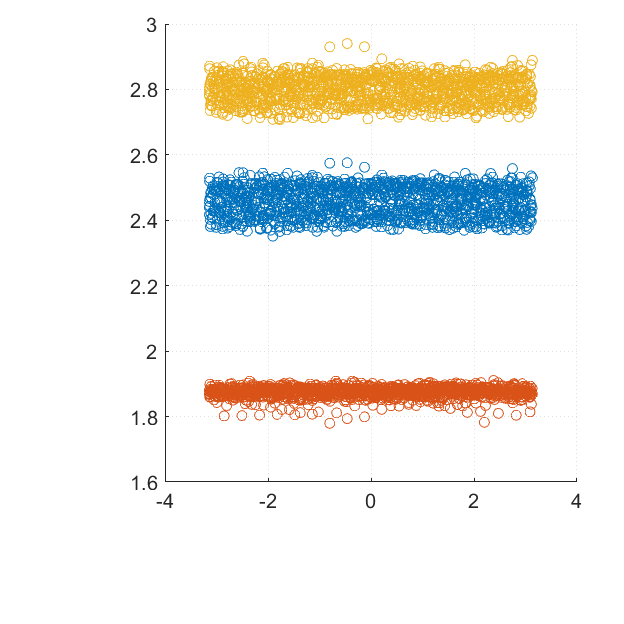

tfaultstart = 35;
tfaultend = 60;
samplevector = tfaultstart*logSampleRate:1:tfaultend*logSampleRate;
figure(13)
clf
scatter(psi(samplevector), tDes(samplevector,2))
hold on
scatter(psi(samplevector), tDes(samplevector,3))
hold on
scatter(psi(samplevector), tDes(samplevector,4))

figure(14)
clf



# 2. 旋转轴的估计\机体角速率跟踪\主轴跟踪

飞机做前飞后飞动作

clear
clc
 
ulogOBJ = ulogreader("log_1_2021-6-30-08-05-20.ulg");
msg = readTopicMsgs(ulogOBJ);

## 2.1旋转轴的估计

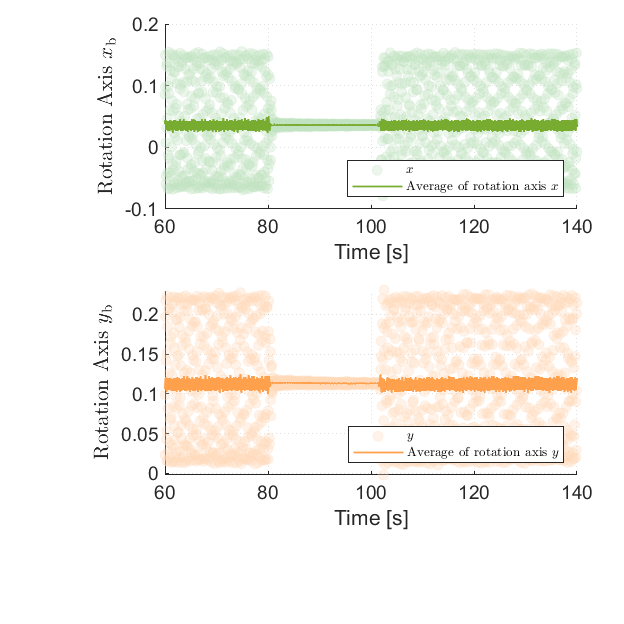

% 获取 vehicle_attitude 数据
logSampleRate = 20;
vehicle_attitude = msg.TopicMessages{35};
% 生成相对时间
log_time = vehicle_attitude.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 得到yaw为0的(无旋转的)旋转矩阵,并根据此得出机体旋转轴,相对的也可以理解为是地球坐标系的向量投射到机体系(无旋转)
% 左前方旋翼失效,俯仰角应该小于0, 横滚角应该大于0. 需要加上耦合项到控制器中
quate = vehicle_attitude.q;
quate(:,1) = quate(:,1);
[vehicle_attitude_psi, pitch, roll] = quat2angle(quate);%该矩阵可以将地球坐标系下的向量投射到机体坐标系,反之是将向量旋转-roll和-pitch
% 计算倾斜矩阵(无旋转)(e-->b)
yaw = zeros(sample_count,1);
angle = angle2dcm(yaw,pitch,roll);

% 利用倾斜矩阵计算旋转轴
rotation_axis = zeros(sample_count,3);
for i=1:sample_count
    % angle(:,:,i)*[0,0,1]' 看作是机体系的Z轴经过旋转矩阵旋转后的向量, 这是看作向量的旋转而非坐标系的转换.
    % 如何理解呢? 将手臂想象为旋转时候的旋转轴, 手握笔杆做一定的倾斜, 笔杆看作机体Z轴, 机体Z轴绕旋转轴旋转.
    % 当然确实可以看作是地球坐标系的Z轴在机体系中的投影(但是不便于解释), 因为旋转矩阵本身就有两种含义. 
    rotation_axis(i,:) = angle(:,:,i)*[0,0,1]';
end
% 获取滤波数据 零相位滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2.5,'SampleRate',20);
rotation_axis_xf = filtfilt(d,double(rotation_axis(:,1)));
rotation_axis_yf = filtfilt(d,double(rotation_axis(:,2)));
rotation_axis_zf = filtfilt(d,double(rotation_axis(:,3)));

% % 绘制欧拉角的图
% s = figure(21);
% clf
% subplot(2,1,1)
% plot(relativeTime,roll)
% % xlim([16, 19])
% 
% subplot(2,1,2)
% plot(relativeTime,pitch)
% xlim([16, 19])

%% 绘图主轴估计图
s = figure(22);
% s.Position(4) = 8.0;
clf
subplot(2,1,1)
% area(relativeTime,rotation_axis(:,1),'FaceColor','#c0e2c0','EdgeColor','#c0e2c0','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5,'BaseValue',-0.02)
scatter(relativeTime,rotation_axis(:,1),'MarkerEdgeColor','#c0e2c0','MarkerFaceColor',"#c0e2c0",'MarkerEdgeAlpha',.3,'MarkerFaceAlpha',.3)
hold on
plot(relativeTime,rotation_axis_xf,'LineWidth',1,'Color','#77AC30')
xlim([60, 140])
% ylim([-0.1 0.03])
xlabel("Time [s]")
ylabel("Rotation Axis $x_{\mathrm{b}}$","Interpreter","latex")
legend('$x$','Average of rotation axis $x$',"Interpreter","latex",'Location',"best")
legend('Box',"on",'FontSize',8)

subplot(2,1,2)
% area(relativeTime,rotation_axis(:,2),'FaceColor','#ffd8b7','EdgeColor','#ffd8b7','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5,"BaseValue",0.1)
scatter(relativeTime,rotation_axis(:,2),'MarkerEdgeColor','#ffd8b7','MarkerFaceColor','#ffd8b7','MarkerEdgeAlpha',.3,'MarkerFaceAlpha',.3)
hold on
plot(relativeTime,rotation_axis_yf,'LineWidth',1,'Color','#ffa04d')
xlim([60, 140])
% ylim([-0.3 0.2])
xlabel("Time [s]")
ylabel("Rotation Axis $y_{\mathrm{b}}$","Interpreter","latex")
legend('$y$','Average of rotation axis $y$',"Interpreter","latex",'Location',"best")
legend('Box',"on",'FontSize',8)

## 2.2 旋转轴成形度

机体旋转轴在地球坐标系下的坐标

根据前面的部分可知, 机体的旋转轴在机体系下的坐标大致为[0.036  0.114 0.9928]

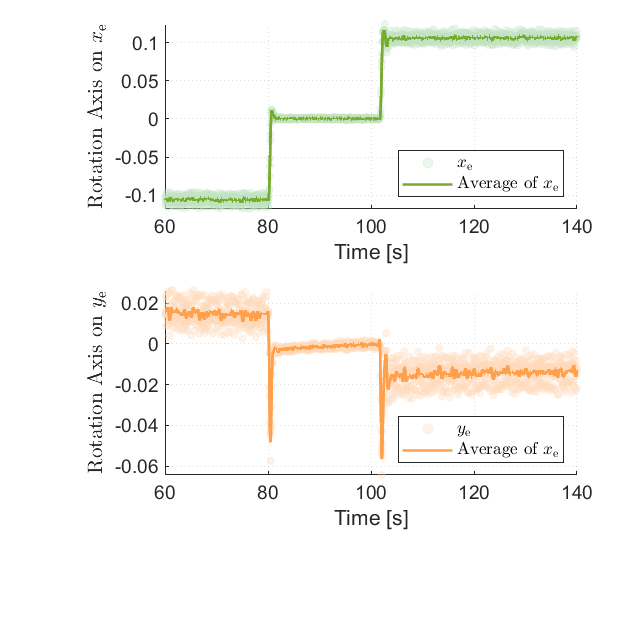

% 将四元数转换为旋转矩阵
vehicle_attitude_dcm = quat2dcm(quate);
% 利用旋转矩阵, 将估算出的机体旋转轴映射到地球坐标系中(旋转矩阵的顺序应该是将向量从及体系到地球系的转换即b-->e,而这里得出的矩阵是e-->b, 因此需要对矩阵进行转置)
rotation_axis_e = zeros(sample_count,3);
for i=1:sample_count
    rotation_axis_e(i,:) = vehicle_attitude_dcm(:,:,i)'*[0.036  0.114 0.9928]';
end
% 获取滤波数据 零相位滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2,'SampleRate',20);
rotation_axis_e_xf = filtfilt(d,double(rotation_axis_e(:,1)));
rotation_axis_e_yf = filtfilt(d,double(rotation_axis_e(:,2)));
rotation_axis_e_zf = filtfilt(d,double(rotation_axis_e(:,3)));
% 绘制图像
figure(23)
% 滤波前的旋转轴在地球坐标系下的投影
clf
subplot(2,1,1)
scatter(relativeTime,rotation_axis_e(:,1),18,'o','MarkerEdgeColor',"#c0e2c0","MarkerFaceColor","#c0e2c0","MarkerEdgeAlpha",0.3,"MarkerFaceAlpha",0.3)
hold on
plot(relativeTime,rotation_axis_e_xf,'Color','#77AC30','LineWidth',1.5)
xlim([60, 140])
xlabel("Time [s]")
ylabel("Rotation Axis on $x_\mathrm{e}$","Interpreter","latex")
legend("$x_\mathrm{e}$","Average of $x_\mathrm{e}$","Interpreter","latex",'Location',"best")

subplot(2,1,2)
scatter(relativeTime,rotation_axis_e(:,2),18,'o','MarkerEdgeColor',"#ffd8b7","MarkerFaceColor","#ffd8b7","MarkerEdgeAlpha",0.3,"MarkerFaceAlpha",0.3)
hold on
plot(relativeTime,rotation_axis_e_yf,'Color','#ffa04d','LineWidth',1.5)
xlim([60, 140])
xlabel("Time [s]")
ylabel("Rotation Axis on $y_\mathrm{e}$","Interpreter","latex")
legend("$y_\mathrm{e}$","Average of $x_\mathrm{e}$","Interpreter","latex",'Location',"best")

## 2.3 机体角速率跟踪

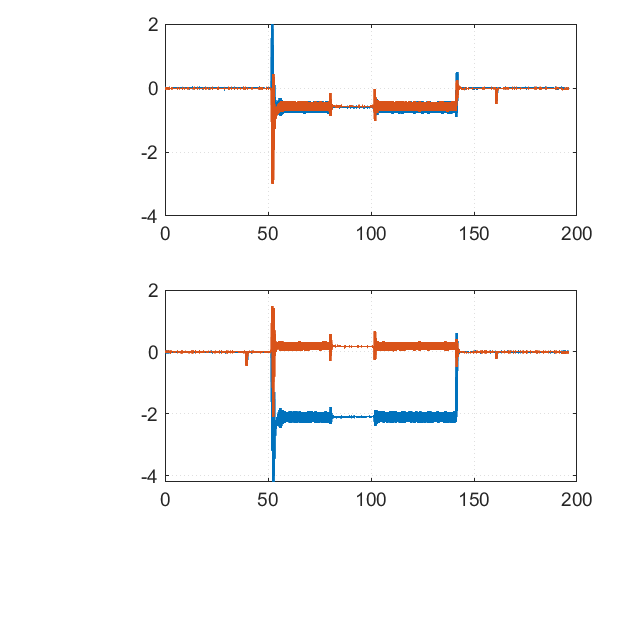

% 获取 unknown_logger 数据
logSampleRate = 50;
unknown_logger = msg.TopicMessages{32};
% 生成相对时间
log_time = unknown_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
pq = unknown_logger.pq;
pqd = unknown_logger.pqd;

% 画图
figure(24)
clf
subplot(2,1,1)
plot(relativeTime, pq(:,1))
hold on
plot(relativeTime, pqd(:,1))
% xlim([100,120])

subplot(2,1,2)
plot(relativeTime, pq(:,2))
hold on
plot(relativeTime, pqd(:,2))

% xlim([100,120])

## 2.4 机体主轴跟踪

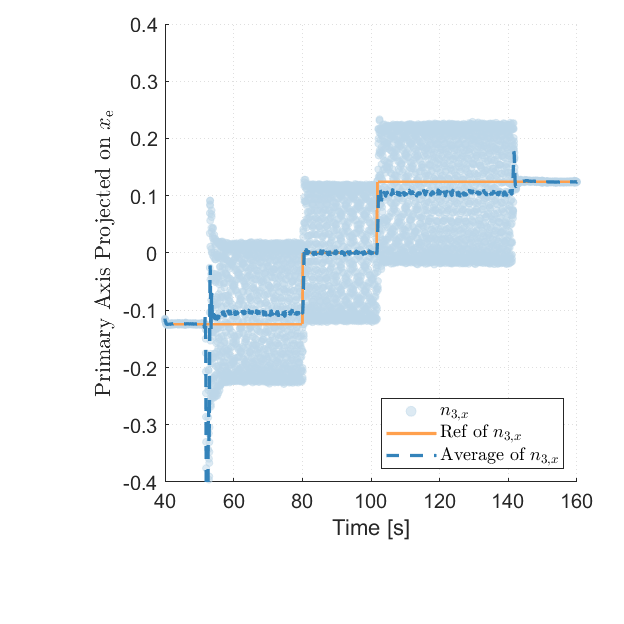

% 获取数据
h1 = unknown_logger.h1;
h2 = unknown_logger.h2;
h1d = unknown_logger.h1d;
h2d = unknown_logger.h2d;
% 进行滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2,'SampleRate',50);
h1f = filtfilt(d,double(h1));
h2f = filtfilt(d,double(h2));

% 画图
figure(25)
clf
scatter(relativeTime, h1,18,'o','MarkerEdgeColor',"#bcd6e8",'MarkerFaceColor','#bcd6e8','MarkerEdgeAlpha',0.5,'MarkerFaceAlpha',0.5)
hold on
plot(relativeTime, h1d,'Color','#ffa04d','LineWidth',2)
hold on
plot(relativeTime, h1f,'--','Color','#3483ba','LineWidth',2)
xlim([40, 160])
ylim([-0.4 0.4])
legend('$n_{3,x}$','Ref of $n_{3,x}$','Average of $n_{3,x}$',"Interpreter","latex",'Location',"best")
xlabel("Time [s]")
ylabel("Primary Axis Projected on $x_{\mathrm{e}}$","Interpreter","latex")

# 3.位置环仿真

clear
clc
 
ulogOBJ = ulogreader("log_3_2021-6-30-08-05-42.ulg");
msg = readTopicMsgs(ulogOBJ);

% 获取 vehicle_local_position 数据
logSampleRate = 10;
vehicle_local_position = msg.TopicMessages{43};
% 生成相对时间
log_time = vehicle_local_position.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));
% 获取数据
px = vehicle_local_position.x;
pz = vehicle_local_position.z;
figure(31)
clf
subplot(3,2,1)
plot(relativeTime, px)
xlim([0,120])
ylabel("Pos x[m]")

subplot(3,2,3)
plot(relativeTime, -pz)
xlim([0,120])
ylabel("Alt [m]")

a

% 获取 unknown_logger 数据
logSampleRate = 50;
unknown_logger = msg.TopicMessages{32};
% 生成相对时间
log_time = unknown_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));
% 获取数据
pq = unknown_logger.pq;
pqd = unknown_logger.pqd;
h1 = unknown_logger.h1;
h2 = unknown_logger.h2;
h1d = unknown_logger.h1d;
h2d = unknown_logger.h2d;

% 画图
subplot(3,2,2)
plot(relativeTime, pq(:,1))
hold on
plot(relativeTime, pqd(:,1))
ylabel("$p$ [rad/s]",'Interpreter',"latex")
xlim([0,120])

subplot(3,2,4)
plot(relativeTime, pq(:,2))
hold on
plot(relativeTime, pqd(:,2))
ylabel("$q$ [rad/s]",'Interpreter',"latex")
xlim([0,120])

subplot(3,2,5)
plot(relativeTime, h1)
hold on
plot(relativeTime, h1d)
ylabel("$n_{3,x}$",'Interpreter',"latex")
xlim([0,120])
ylim([-0.3, 0.3])

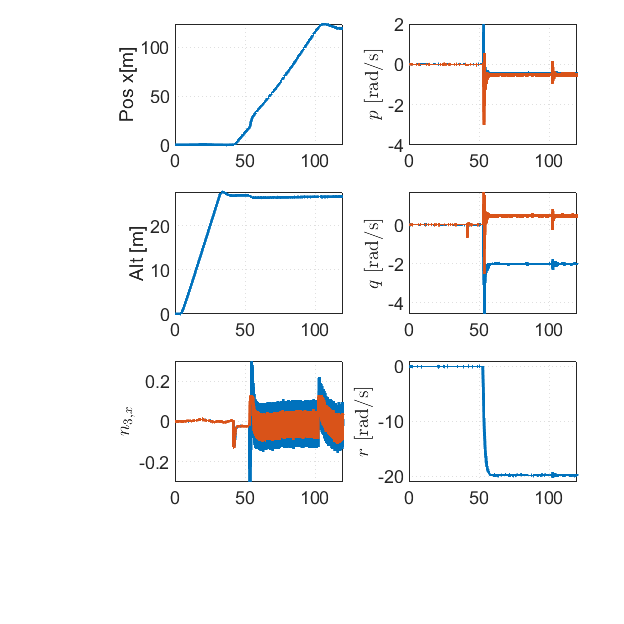

% 获取 sensor_combined 数据
logSampleRate = 200;
sensor_combined = msg.TopicMessages{22};
% 生成相对时间
log_time = sensor_combined.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));
% 获取数据
gyro = sensor_combined.gyro_rad;
subplot(3,2,6)
plot(relativeTime, gyro(:,3))
xlim([0,120])
ylabel("$r$ [rad/s]",'Interpreter',"latex")
ylim([-21, 1])